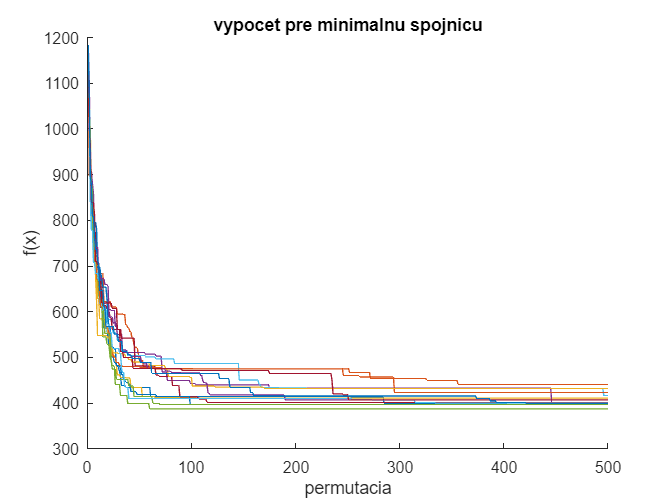

value = 396.3443

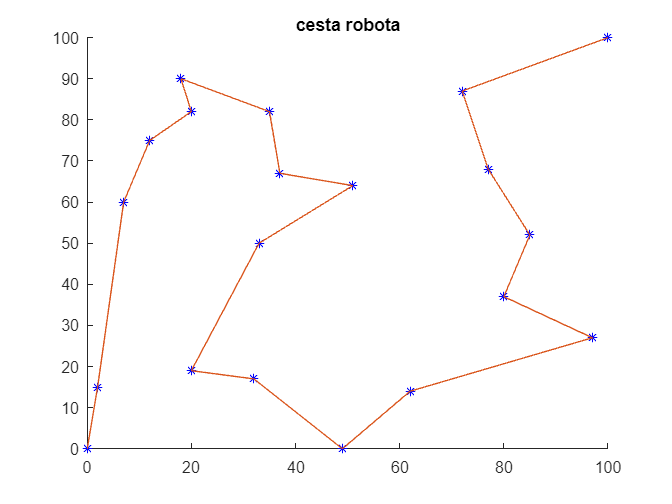

value = 441.0444

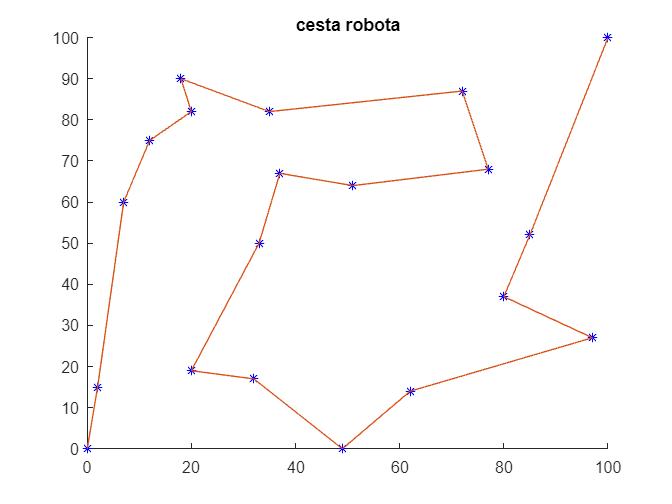

value = 410.9962

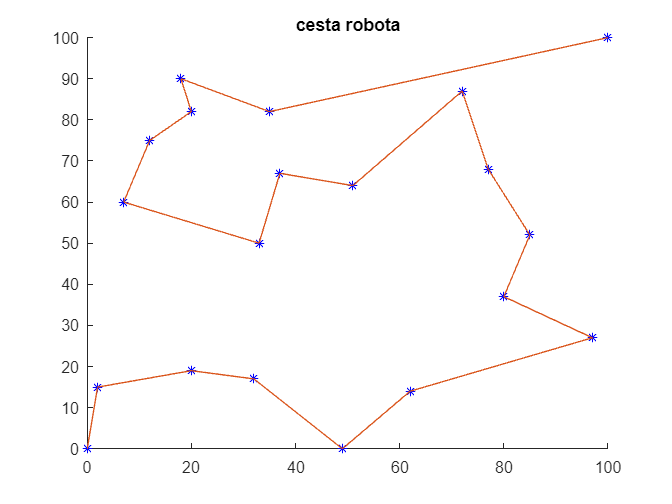

value = 401.3783

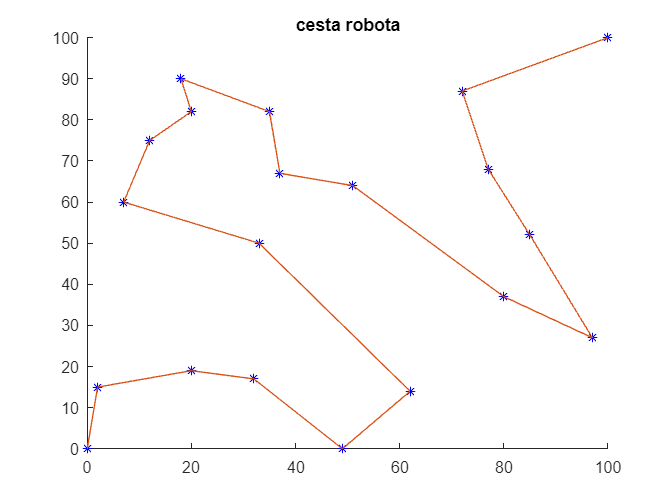

value = 387.2711

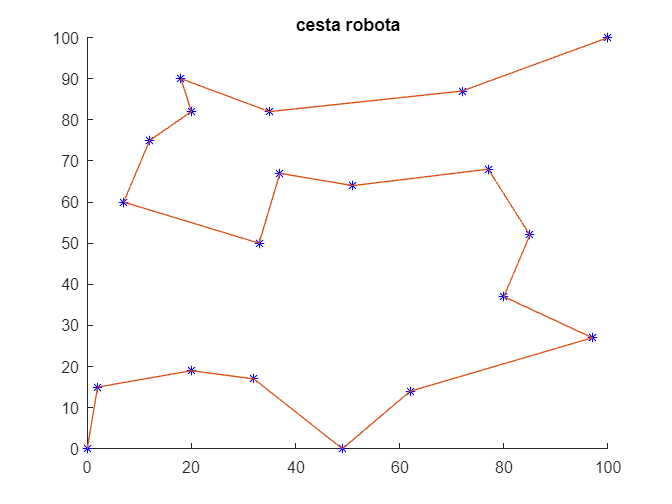

value = 416.4382

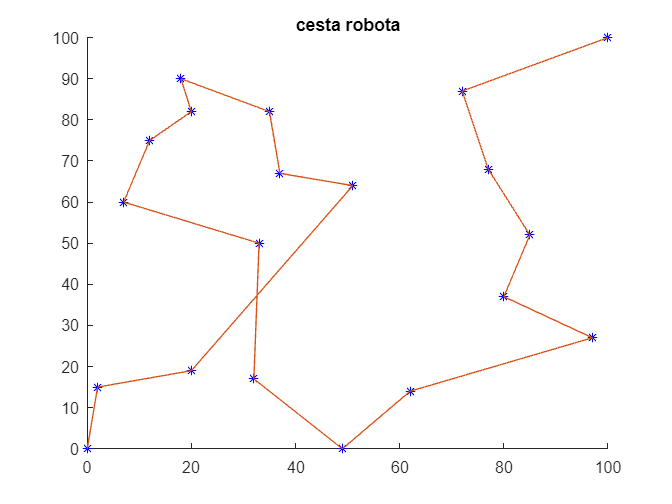

value = 401.3783

value = 396.3443

value = 423.1714

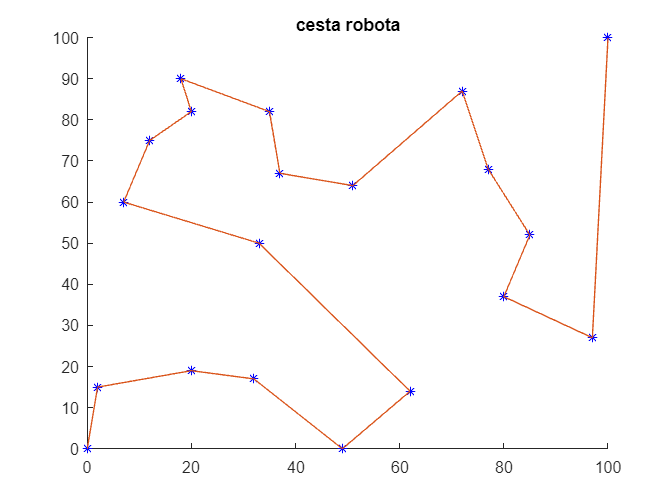

value = 431.6421

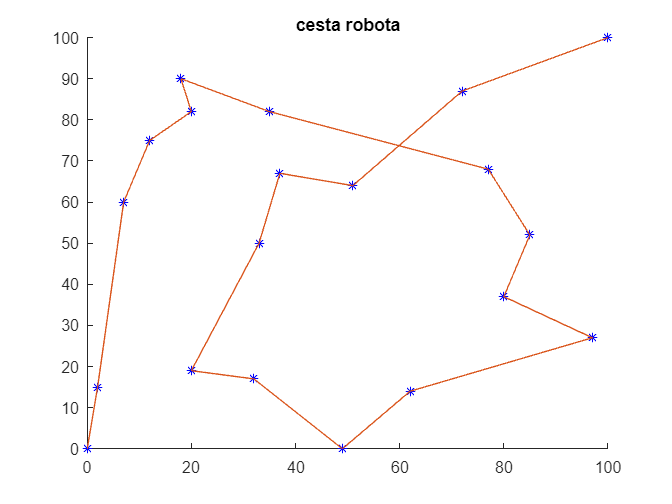

value = 407.0803

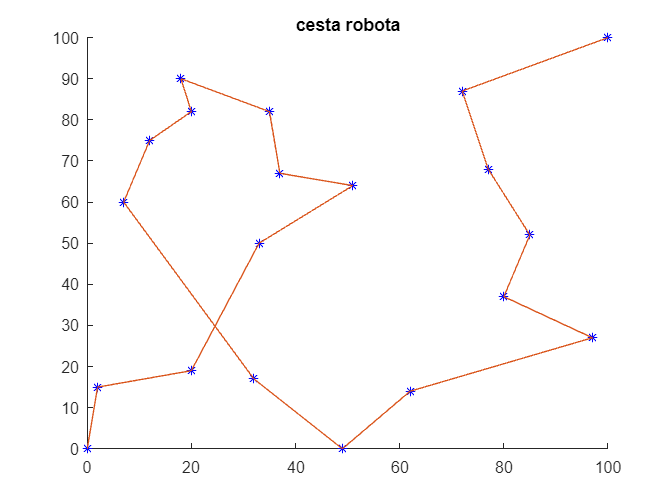

value = 396.3443

value = 400.0114

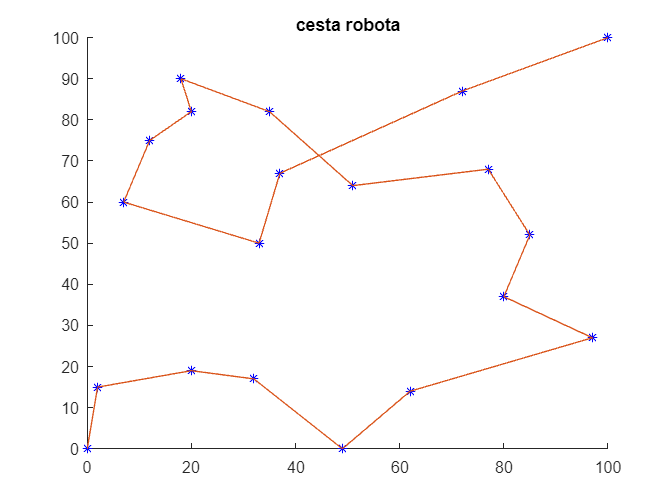

value = 407.0803

value = 399.0456

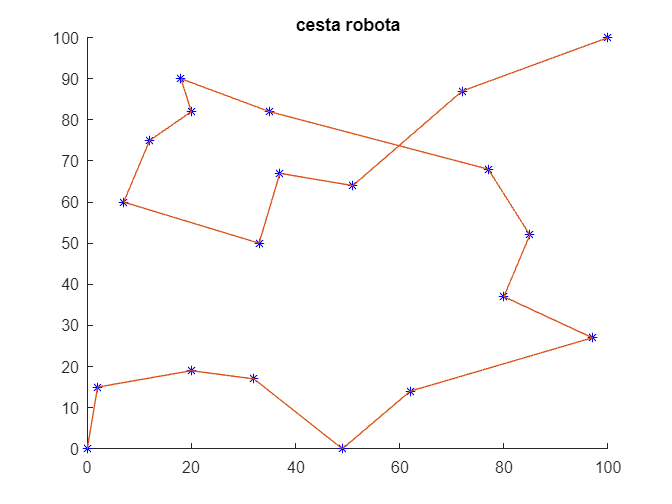

f1 = figure("Name",'graf minimalnej spojnice');
for i = 1:15    
main(f1)
end

figure(f1)

Funkcia na vypocet dlzky spojnice zacinajucej v bode [0,0] a konciacej v bode [100, 100]

function length_v = calculateDist(points, matrix)
length_v = zeros(50,1);
for j = 1:100
    length = 0;
    for i = 1:19
        current = points(matrix(j, i),:);
        next = points(matrix(j, i+1),:);
        distance = norm(next - current);
        length = distance + length;
    end
    length_v(j) = length;
end
end

upraveny geneticky algoritmus

function [flowLines, minValues, vector] = algorithm(matrix, minValues, flowLines, points)
for i = 1:500
    length = calculateDist(points, flowLines);
    minValues(i) = min(length);
    bestTwo = selbest(matrix, length, ones(1,2));
    L_v1 = seltourn(matrix, length, 25);
    L_v2 = selsort(matrix, length, 24);
    L_v3 = seltourn(matrix, length, 24);
    L_v4 = selrand(matrix, length, 25);
    L_v1 = crosord(L_v1, 0);
    L_v1 = swapgen(L_v1, 0.15);
    L_v2 = crosord(L_v2, 0);
    L_v2 = swappart(L_v2, 0.15);
    L_v3 = crosord(L_v3, 1);
    L_v3 = swappart(L_v3, 0.15);
    L_v4 = crosord(L_v4, 1);
    L_v4 = swapgen(L_v4, 0.15);
    matrix = [bestTwo; L_v1; L_v2; L_v3; L_v4];
    flowLines = [ones(100,1), matrix, ones(100,1)*20];
end
length = calculateDist(points, flowLines);
minValues(i) = min(length);
vector = selbest(matrix, length, 1);
end

Implementacia vytvotenych funkcii 

function main(figure1)
    B=[0,0; 77,68; 12,75; 32,17; 51,64; 20,19; 72,87; 80,37; 35,82;
2,15; 18,90; 33,50; 85,52; 97,27; 37,67; 20,82; 49,0; 62,14; 7,60;
100,100];
    vector = (2:19);    
    matrix = repmat(vector, 100, 1);
    minValues = zeros(1, 500);
    flowLines = [ones(100,1), matrix, ones(100,1)*20];
    [flowLines, minValues, best_P] = algorithm(matrix, minValues, flowLines, B);
    best_V = [1, best_P, 20];
    [value, index] = min(calculateDist(B, flowLines));
    
    value
    figure2 = figure;
    

    figure(figure1);
    hold on
    D_f = (1:500);
    plot(D_f,minValues);
    title("vypocet pre minimalnu spojnicu")
    xlabel("permutacia")
    ylabel("f(x)")

    
    figure(figure2);
    hold on
    title("cesta robota")
    plot(B(:,1), B(:,2), "b*")
    plot(B(flowLines(index, :), 1), B(flowLines(index,:), 2))
    
end
